# Basic primer on Bayesian inference, with code

This tutorial was inspired by the probability and Bayesian statistics chapters in Russ Poldrack's book, Statistical Thinking for the 21st Century

https://statsthinking21.github.io/statsthinking21-core-site/bayesian-statistics.html

And Ryan Smith's tutorial on active inference

### Likelihood and relationship to probability density function

For Bernoulli trials, the binomial distribution describes the likelihood of observing an outcome (Data, D) given a belief about the underlying generative (causal) model (M).  

For example, my model might be that a coin is fair, yielding heads or tails with 50% probability, so M is that P(heads) = 0.5.  Here, D describes a set of observations together (not necessarily a single observation). For example, it could describe the number of heads X in N coin flips, e.g., obtaining 2 heads out of 10 flips. 

The binomial distribution describes the ***likelihood*** of observing the data given the model, written **P(D | M)**.  


figure; plot([0:10], Y);
X = [0:10];
Y = binopdf(X, 10, 0.5)


The binomial PDF describes the probability of getting each discrete outcome (e.g., exactly 7 heads) given the model. We can use the cumulative density function (CDF) to define the probability of any given outcome of interest, e.g., getting at least 7 heads in 10 coin flips:

cum_p = binocdf(6, 10, 0.5, 'upper')


binocdf tests the probability of > X heads | N, P, not >=.  So 0.055 is the probability P(n>7|pheads=0.5).

### **Diagnostic testing: Sensitivity, specificity, base rates and PPV**

One of our goals here is to relate this to diagnostic testing. In diagnostic testing, the likelihood of obtaining a positive result **D** given underlying model **M, P(D | M),** is the **sensitivity** of the test. It is a probability ranging from, or *on the interval*, [0 1].  In this case, D is a test result and M is a hypothesis.  For example, M might be the hypothesis that a person has tuberculosis (either 1 for true or 0 for false), and D might be a test result (either 1 for positive or 0 for negative). The likelihood of obtaining a positive test (D = 1) given the person has TB (M = 1) is the test's **sensitivity**. 

The likelihood of obtaining a negative test (D = 0) given the person does not have TB (M = 0) is the test's **specificity**. In a simple binary case we can write this as **P(~D | ~M). **

The final, critical number we need is the **prior probability** that a person has TB, without observing any data, or **P(M)**. In diagnostic testing, this is also called the **base rate**. 

Often, what we'd like to know is the probability of an underlying model M given D, **P(M | D)**. For example, we may want to know the probability that a person has TB given a positive result, or the probability that a hypothesis is true given the results of a statistical test. 

Bayes' Rule can be used to calculate **P(M | D**). In Bayesian analysis generally, this is called the **posterior probability** of model M after observing data D.  In diagnostic testing, this is called the ***Positive Predictive Value***.  In statistical testing, this is sometimes called "reverse inference" or "inverse inference". In the simplest case, M is a hypothesis that is either true or false.

% P(M|D) = P(D|M)*P(M) ./ (P(D|M)*P(M) + P(D|~M)*P(~M))

% Bayes' Rule for a binary model (i.e., hypothesis of M {true, false})

Bayes Rule is a fundamental theorem in probability, and in the diagnostic testing and hypothesis testing case, the posterior probability of model or hypothesis M is defined by three values:

Sensitivity

Specificity

Prior or base rate          

We can define a function that encapsulates Bayes Rule in this case, and relates the posterior probability (or PPV) to these three quantities:

bayes_modelprob_binary = @(sens, spec, prior) sens * prior ./ (sens * prior + (1 - spec) * (1-prior));

Now we can think about what the results of a positive test means: 

% Sensitivity
sens =0.84

sens =    0.840000000000000


% Specificity
spec =0.95

spec =    0.950000000000000


% Prior
prior = 0.003

prior =    0.003000000000000



posterior = bayes_modelprob_binary(sens, spec, prior)

posterior =    0.048119152186366


This shows that even if a test (e.g., for TB) has very high sensitivity and specificity, the probability of having TB given a positive test result is very low if the base rate of TB is low. In this case, with 99% sensitivity, 98% specificity, and a base rate of 1/1000, the PPV is only 0.0472.  You have only a 5% chance of having TB given a positive test result!  

More generally, the PPV depends very strongly on the prior and the specificity, and very little on the sensitivity of the test. This is intuitive because the prior determines the overall likelihood of having TB, and the specificity determines how likely it is that a positive test is a false positive. Unlikely conditions (or hypotheses) require extraordinary evidence to shift belief, so conditions with low base rates require very specific tests to be useful. The more unlikely the prior, the more specific the test must be. You can play with the sliders above to explore this concept. 

### **Accumulating evidence across repeated observations**

What if we test repeatedly and accumulate evidence across mulitple tests?  If we assume the test results are independent, we can use Bayes Rule to integrate information across multiple tests. 

sens = 0.99; % p(D|M).  This is also power in hyp testing.
spec = 0.98; % 1 - p(D|~M). Specificity is 1-alpha in hyp testing
prior = 1 / 1000; %971595898; % Prior probability of M before observing data

% Probability of M given one 
bayes_modelprob_binary(sens, spec, prior)

ans =    0.047210300429185


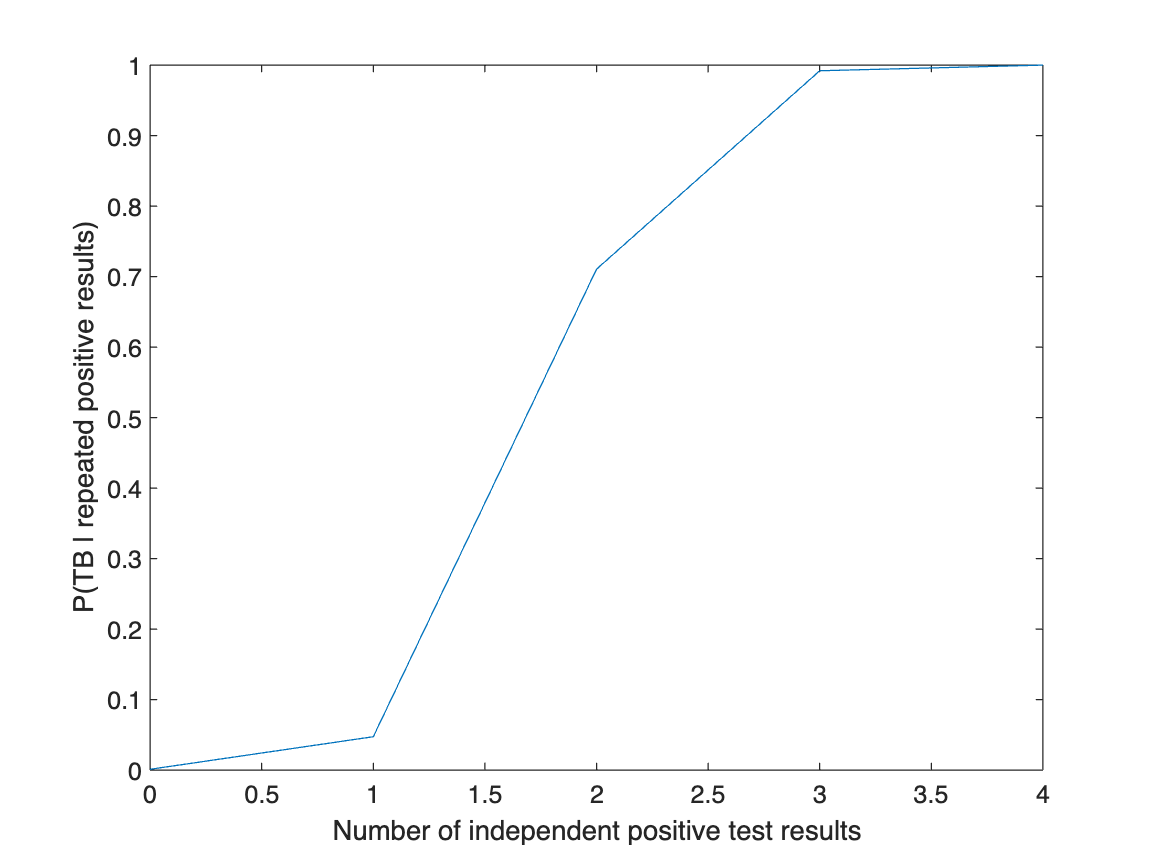


% The posterior becomes the new prior, allowing us to integrate
% information:

repeated_tests = 0:4;

% when i = 1, num results = 0
for i = 1:length(repeated_tests) - 1
    prior(i+1) = bayes_modelprob_binary(sens, spec, prior(i));
end

figure; plot(repeated_tests, prior)
xlabel('Number of independent positive test results')
ylabel('P(TB | repeated positive results)')

This shows that the probability of having TB given 1 positive test is only 5%, but with two independent positive tests it rises to about 70%, and above 99% with 3 independent positive tests.

What if we get a series of positive and negative tests?  

Let's say we start with a prior of 71% after 2 positive TB tests, but then we get a negative result. What is our estimate of whether we have TB (P(M)) now? Let's define a function that gives us this result:

bayes_binary_negresult = @(sens, spec, prior) 1 - bayes_modelprob_binary(spec, sens, 1 - prior);

In this case, for a negative result, we have to calculate the PPV of M given D = 0 (or ~D).  In this case, we can use Bayes Rule to estimate the PPV for ~M. Because we are calculating P(~M | ~D), we need to enter the prior for ~M as well.  This is 1 - P(M) in this case, or 1 - prior in the previous example, because P(M) + P(~M) = 1 by definition (M is either true or false). The result is the PPV for ~M, which we convert to PPV for M by taking 1 - PPV(~M). 

posterior = bayes_binary_negresult(sens, spec, 0.71)

posterior = 0.1141

Now we can define a function that gives us the posterior belief given a series of positive and negative results, and our other parameters of sensitivity, specificity, and starting prior. The function is at the end of this script.

sens = 0.95;        % p(D|M). 
spec = 0.95;        % 1 - p(D|~M). 
prior = 1 / 1000;   % P(M)

test_results = [1 1 0 1 1 0 0 1 1 1];

posterior = posterior_belief(sens, spec, prior, test_results);
figure; hold on;
plot(posterior)
xlabel('Test number'); ylabel('Posterior probability of TB')


Sensitivity determines how informative a negative result is: With high sensitivity, we can assume we would have tested positive if the disease is really present. Specificity determines how informative a positive result is: With high specificity, we can assume we would not have tested positive unless the disease is really present.  

Let's try the same thing, varying sensitivity and specificity independently, and keeping the series of positive and negative test results and the prior constant:

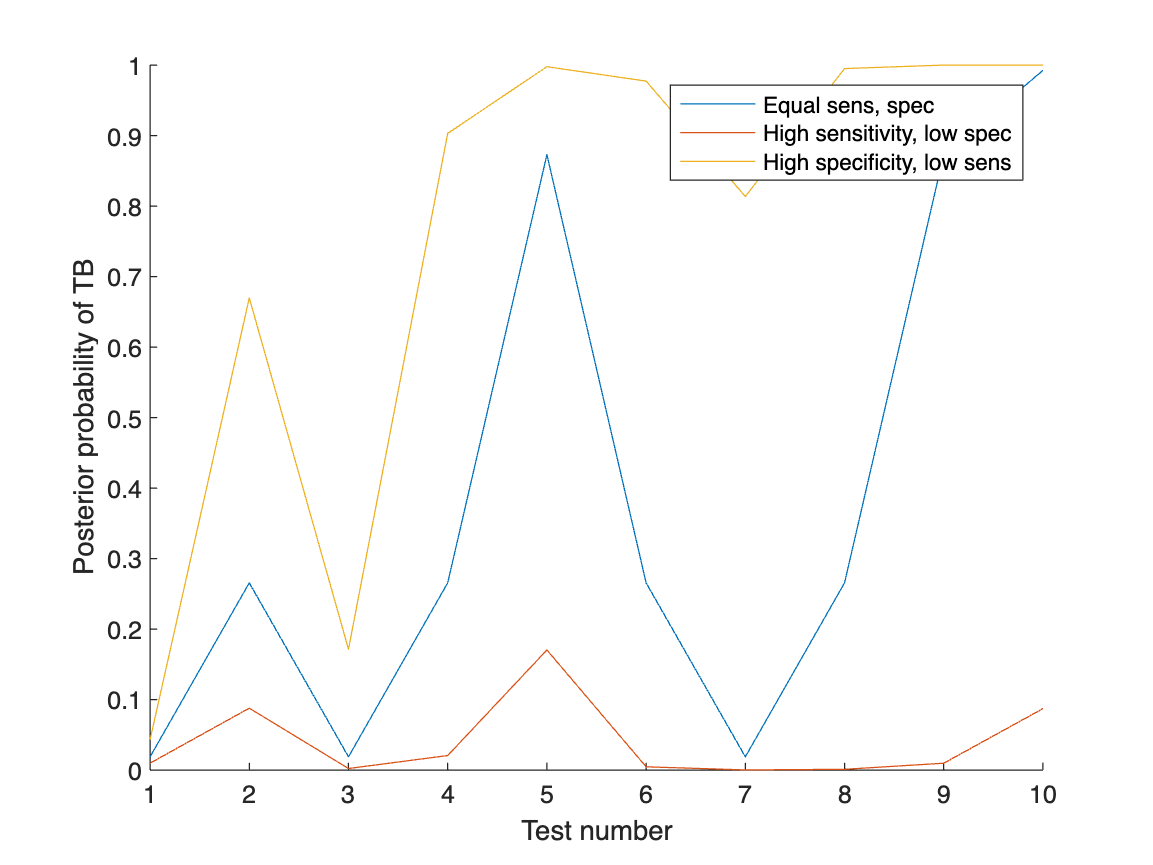

plot(posterior_belief(.98, .90, prior, test_results));
plot(posterior_belief(.9, .98, prior, test_results));

legend({'Equal sens, spec', 'High sensitivity, low spec', 'High specificity, low sens'})

What if we permute the order of the positive and negative tests? The Bayesian integration of evidence takes into account the entire history and weights each observation equally, so at the end of 10 tests, we get the same result no  matter which order they occur in. 

Above, we have 7 positive findings in 10 tests.  Let's look at one fixed rearrangement of the order of these findings and 3 random orders:

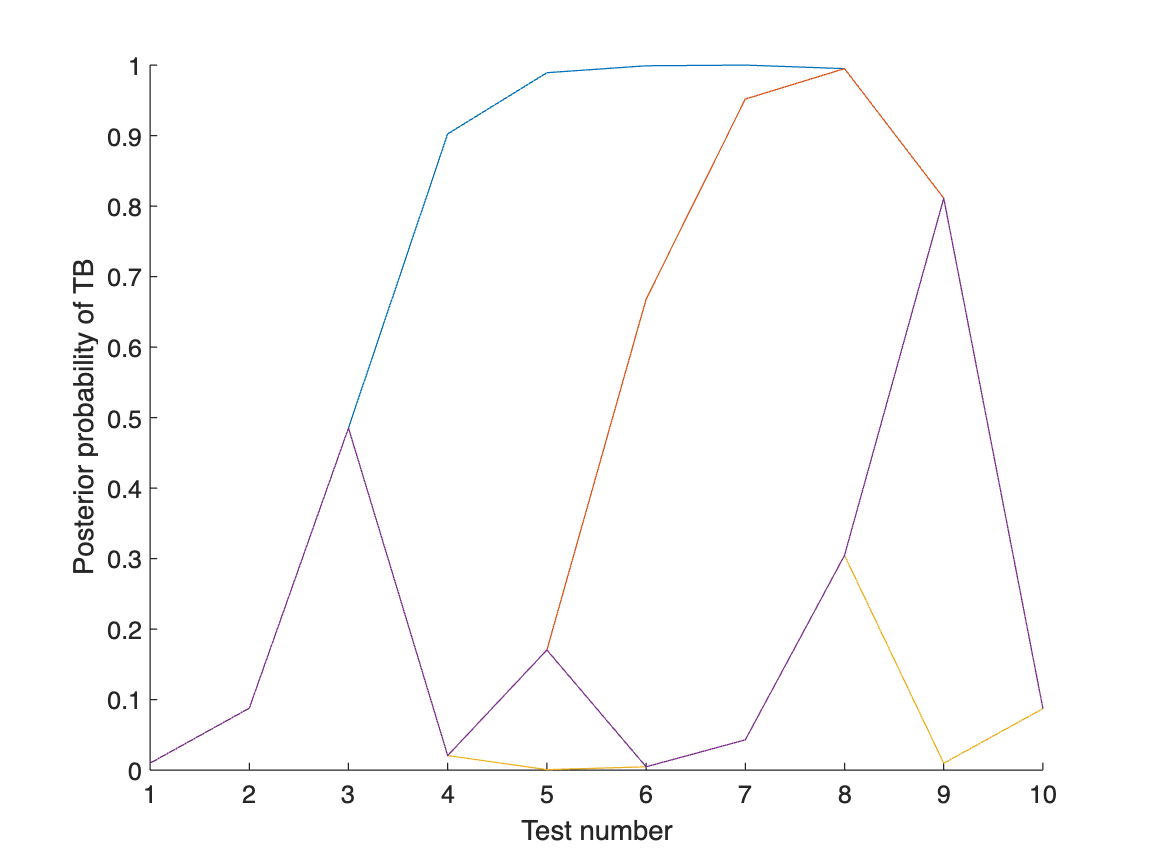

test_results = [1 1 1 1 1 1 1 0 0 0];
posterior = posterior_belief(.98, .90, prior, test_results);
figure; hold on;
plot(posterior)
xlabel('Test number'); ylabel('Posterior probability of TB')

test_results = test_results(randperm(length(test_results)));
plot(posterior_belief(.98, .90, prior, test_results));

test_results = test_results(randperm(length(test_results)));
plot(posterior_belief(.98, .90, prior, test_results));

test_results = test_results(randperm(length(test_results)));
plot(posterior_belief(.98, .90, prior, test_results));

In all cases, the posterior probability of TB is the same after all series, around 9%.  

Why is it so low after 7 positive findings?  We have a low base rate and relatively low sensitivity (though it's still 90%!), so it's hard to establish that our positive results are really definitive evidence for TB.

### Unknown unknowns!!

**!! Why this simple example could be misleading**!!  Note that the assumption that repeated tests are independent may be a big assumption in practice. Tests could be contaminated across a whole batch, or interact with a person's biology in ways not accounted for by established population values for sensitivity and specificity.  These effects are related to the idea of *correlated errors* in statistics in general, and they will make the estimated PPV inaccurate in unpredictable ways.  In addition, specificity is particularly tricky because it always depends on what other diseases are present in a population.  A test that is specific in one population, e.g., a TB test in the U.S., may lack specificity in a different population that has other diseases that may be confusable with it.  More generally, specificity can only be defined relative to a set of alternative confusable conditions. The alternatives may not be known or may not even exist in the population in which specificity is estimated. This example illustrates how our ability to trust our probability estimates (and thus perform all kinds of statistical inference) depends on assumptions -- and the assumptions are often impossible to fully check and verify.  That's why we take our P-values and other probability estimates "with a grain of salt", learning what we can but realizing that there are "unknown unknowns" and repeated verification in different context is critical.  

### Application of Bayesian calculations to hypothesis testing

THIS IS INCOMPLETE AND MISLEADING, DON'T RELY ON IT OR USE IT YET

% In hypothesis testing, sensitivity is equivalent to a test's power.
power =0.8

power =    0.800000000000000


% P-value: Chances of obtaining a positive result by chance
% Specificity is 1 - P-value, or it can be determined by a target false positive rate (alpha)
% value
pvalue =0.05

pvalue =    0.050000000000000


spec = 1 - pvalue;

% Prior probability of hypothesis
prior = 0.5

prior =    0.500000000000000



posterior = bayes_modelprob_binary(sens, spec, prior)

posterior =    0.951923076923077


### From Bernoulli trials to continuous outcomes

THE REST OF THIS IS INCOMPLETE, DON'T RELY ON IT OR USE IT YET

Key idea: When our model M is not a single binary outcome with two possible values (true or false), things get a bit more complicated. We don't have two possible underlying model states, but multiple states or even infinite ones.  For example, if I flip 10 coins, I could get anywhere from 0 to 10 heads. One possible model M is that the coin is fair (P(heads) = 0.5). But there is not just one alternative model, but many: The true P(heads) could vary anywhere from 0 to 1.  

Likewise, if I look at the proportion of people in a population who test positive for TB, or whether people perform better on a drug vs. off-drug, there are many possible model states, corresponding to different values of the population parameters involved. 

The calculation of the likelihood of the data (P(D)) becomes more complex because I have to integrate across all possible models (population values), weighted by their prior likelihood.  

*Notes: Need to probably define Result/outcome, etc above more formally.*

Let's map this onto our coin flips.  Let's say we want to tell whether our coin is fair. We decide to flip a coin 10 times and if we get 5 or more heads, we'll decide it's a fair coin. Is this a good test?  If the coin is fair (M: P(heads = 0.5)), we'd expect to get 5 or more heads 62% of the time.  So the sensitivity of the test is 0.62. 

sum(Y(X >= 7))

ans =    0.171875000000000


The trouble here is that we don't have a clear alternative hypothesis. if M = 0, the coin is not fair, but we don't know in what way.  So the specificity of the test will be very hard to calculate.  

## Subfunctions

function posterior = posterior_belief(sens, spec, prior, test_results)

% bayes_binary_posresult = @(sens, spec, prior) sens * prior ./ (sens * prior + (1 - spec) * (1-prior));
% bayes_binary_negresult = @(sens, spec, prior) 1 - bayes_binary_posresult(spec, sens, 1 - prior);

for i = 1:length(test_results)

    switch test_results(i)
        case true
            posterior(i) = sens * prior(i) ./ (sens * prior(i) + (1 - spec) * (1-prior(i)));
        
        case false
            posterior(i) = 1 - (spec * (1 - prior(i)) ./ (spec * (1 - prior(i)) + (1 - sens) * (prior(i))));

    end

    prior(i + 1) = posterior(i);

end

end
